program

clc;
clear;
x = linspace(-1.5,3.5,100);

%przedzialy = [6 8; 8.3 10; 12 15];
dokladnosc_zer = 0.01;

% m_zerowe = MM1(-2, -1, 0, dokladnosc_zer)
% m_zerowe = MM1(-5, -4, -3, dokladnosc_zer)
% m_zerowe'
% abs(wartosc_funkcji(m_zerowe))
% m_zerowe = MM1(2, 2.5, 3, dokladnosc_zer)
% m_zerowe = MM1(-1.5, -1, -.075, dokladnosc_zer)

m_zerowe = -0.6702

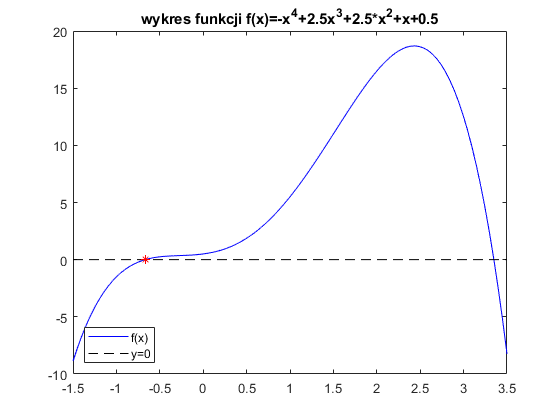


figure
y = wartosc_funkcji(x);
plot(x,y,'b-',[-1.5 3.5], [0 0], 'k--', m_zerowe, wartosc_funkcji(m_zerowe), 'r*');
legend({'f(x)', 'y=0'},'Location','southwest');
title('wykres funkcji f(x)=-x^4+2.5x^3+2.5*x^2+x+0.5');

**funkcje metody Mullera**

metoda MM1

function x = MM1(x1, x2, x3, dokladnosc_zer)
    ilosc_pierwiastkow = 1;
    for i = 1:ilosc_pierwiastkow
        while (abs(wartosc_funkcji(x3))>dokladnosc_zer)
            [x1 x2 x3] = kolejny_punkt(x1,x2,x3);
        end
        x = x3;
    end
end

wyznaczenie kolejnego punktu na podstawie paraboli

function [x1 x2 x3] = kolejny_punkt(x1, x2, x3)
    q = (x3-x2)/(x2-x1);
    a = q*wartosc_funkcji(x3) - q*(q+1)*wartosc_funkcji(x2) + q^2*wartosc_funkcji(x1);
    b = (2*q+1)*wartosc_funkcji(x3) - (q+1)^2*wartosc_funkcji(x2) + q^2*wartosc_funkcji(x1);
    c = (q+1)*wartosc_funkcji(x3);
    
    x1 = x2;
    x2 = x3;
    
    if (b+sqrt(b^2-4*a*c)) > (b-sqrt(b^2-4*a*c))
        x3 = x2 - (x2-x1)*(2*c/(b+sqrt(b^2-4*a*c)));
    else
        x3 = x2 - (x2-x1)*(2*c/(b-sqrt(b^2-4*a*c)));
    end
end

**funkcje pomocnicze dodatkowe**

wyznaczenie wyjsc dla podanych x-ow i zadanej funkcji

function y = wartosc_funkcji(x)
    wielomian = [0.5 1 2.5 2.5 -1];
    rozmiar_w = size(wielomian,2);
    [temp rozmiar_x] = size(x);
    if rozmiar_x == 1
        x = x';
        rozmiar_x = temp;
    end
    y = zeros(rozmiar_x);
    y = y(:,1);
    for i = 1:rozmiar_x
        for j = 1:rozmiar_w
            y(i,1) = y(i,1) + wielomian(j)*(x(1,i))^(j-1);
        end
    end
end

sprawdzenie czy w podanym przedziale jest miejsce zerowe

function result = sprawdzenie_przedzialu(przedzial)
    if wartosc_funkcji(przedzial(1))*wartosc_funkcji(przedzial(2)) < 0
        result = 1;
    else
        result = 0;
    end
end

wartosc najwiekszego bledu

function y = najwieksze_zero(x)
    y = max(abs(wartosc_funkcji(x)));
end

funkcja wektoryzujaca macierz diagonalna

function w = wektor(A)
    rozmiar = size(A);
    for i = 1:rozmiar
        w(i,1) = A(i,i);
    end
end

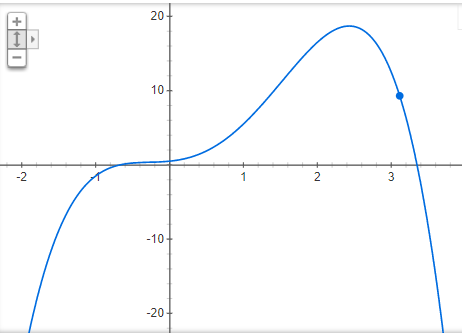

- [https://www.wolframalpha.com/input/?i=-x%5E4%2B2.5x%5E3%2B2.5*x%5E2%2Bx%2B0.5](https://www.wolframalpha.com/input/?i=-x%5E4%2B2.5x%5E3%2B2.5*x%5E2%2Bx%2B0.5)

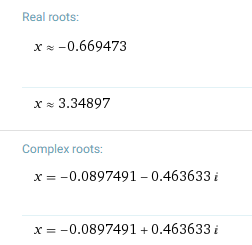

- wzor na kolejnego x: [https://www.youtube.com/watch?v=XIIEjwtkONc](https://www.youtube.com/watch?v=XIIEjwtkONc)